**Translación en la Frecuencia**

%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;
%Traslación en frecuencia
Fs=200;       %Frecuencia de muestreo
t=-1:1/Fs:2;  %Vector de tiempo
L=3000;       %Longitud de la señal 
A=2  ;    %Escalar
s=((4/3)*t-2/3).*(exp(2i*pi*t*A));
Y=fft(s,L);    %Transformada rápida

plot(t,s);

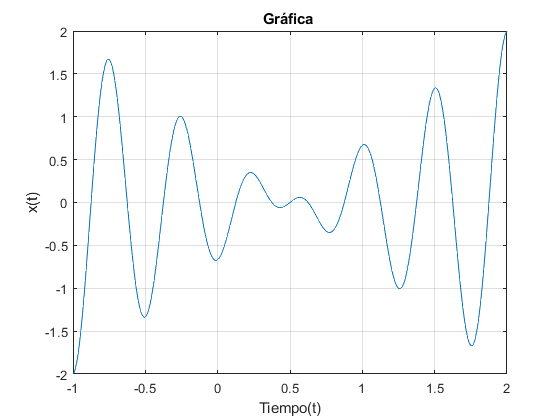

title('Gráfica ')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

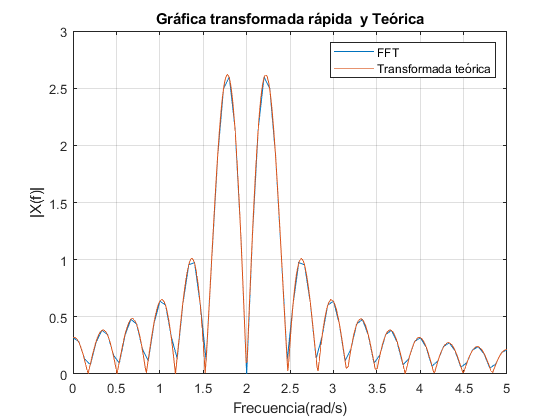

figure   

P=abs(Y/Fs);
f=linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica transformada rápida  y Teórica')
xlabel('Frecuencia(rad/s)')
ylabel('|X(f)|')
grid on


syms t f;       %Variables simbólicas
e=2;
xtf=exp(2*pi*1i*t*e)*((4/3)*t-2/3);
ytf=int(xtf*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica
hold on         %sobreposición
fplot(f,abs(ytf))
legend('FFT','Transformada teórica')
grid on

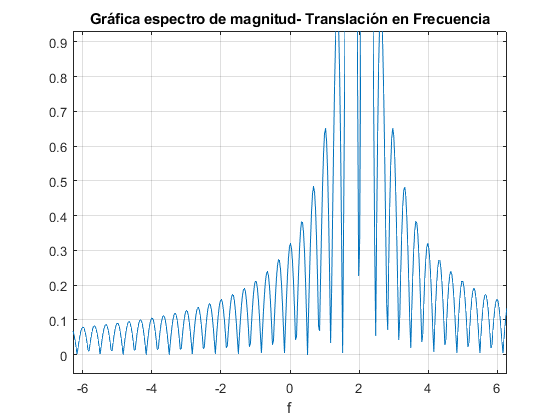

figure

%-----Gráfica espectro de magnitud
ezplot(abs(ytf));
title('Gráfica espectro de magnitud- Translación en Frecuencia')
grid on